# Paper2 Fig4

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2

addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

close all

## 2. Set up LDE firing rate functions

first get basic function information

BgFlag = true;

AngleList = {'0.0','7.5','15.0','22.5'};
AngFuncCtgr = 1;

AngPrint = AngleList{AngFuncCtgr};
Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5
if ~BgFlag
    
    DomList =  {'Small','Larger'}; % we have small, large, larger domains
    
    Large = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{2}),...
        'LDEFrfunc','L4EmeshX','L4ImeshY');
    
    Small = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{1}),...
        'LDEFrfunc','L4EmeshX','L4ImeshY');
else
    DomList =  {'Small','Large'};
    Large = load(sprintf('FuncBG_%s.mat',DomList{2}),'LDEFrfunc','L4EmeshX','L4ImeshY');
    Small = load(sprintf('FuncBG_%s.mat',DomList{1}),'LDEFrfunc','L4EmeshX','L4ImeshY');
end

L4EmeshXLarge = Large.L4EmeshX;
L4ImeshYLarge = Large.L4ImeshY;
LDEFrfuncLarge = Large.LDEFrfunc;

L4EmeshXSmall = Small.L4EmeshX;
L4ImeshYSmall = Small.L4ImeshY;
LDEFrfuncSmall = Small.LDEFrfunc;

if BgFlag
    Cellctgr = fieldnames(LDEFrfuncLarge);
    for CellInd = 1:length(Cellctgr)
        FN = Cellctgr{CellInd};
        LDEFrfuncLargeUse.(FN) = cell(length(AngleList));
        LDEFrfuncSmallUse.(FN) = cell(length(AngleList));
        for cg1 = 1:length(AngleList)
            for cg2 = 1:length(AngleList)
                LDEFrfuncLargeUse.(FN){cg1, cg2} = LDEFrfuncLarge.(FN);
                LDEFrfuncSmallUse.(FN){cg1, cg2} = LDEFrfuncSmall.(FN);
            end
        end
    end
    LDEFrfuncLarge = LDEFrfuncLargeUse;
    LDEFrfuncSmall = LDEFrfuncSmallUse;
end

## 3. Set up initial conditions

N_HCOut = 4; NPixX = 10; NPixY = 10;
load('LDETraces_ang22.5.mat')
LDEEquv = LDEEpoOut{end};
IniNum = 3;
IniDespt = cell(IniNum,1);
LDEIniAll = cell(IniNum,1);
LDEIniAll{1} = LDEEquv;


10 Inis. 3: Horizontal Grating

IniDespt{3} = 'E high I low';
LDEIniAll{3}.S = LDEEquv.S * 0.6;
LDEIniAll{3}.C = LDEEquv.C * 0.6;
LDEIniAll{3}.I = LDEEquv.I * 1.4;

10 Inis. 5: Random Noise

IniDespt{2} = 'Random Noise';
Perc = 0.5;
RandomPert = rand(size(LDEEquv.S))*2*Perc+(1-Perc);
LDEIniAll{2}.S = LDEEquv.S.*RandomPert;
LDEIniAll{2}.C = LDEEquv.C.*RandomPert;
LDEIniAll{2}.I = LDEEquv.I.*RandomPert;

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
LGNlist = 4; L6list = 4;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

Grating = Angle; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
% PhaseFRS_Grating = [45+abs(mod(GratingHC,180)-90)/2;
%                     45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;

FigOn = false;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;

L6smear = n_S_HC*0.30; LGNsmear = n_S_HC*0.10;
Trunc = 1.0;
L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,L6smear,Trunc,FigOn);
LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,LGNsmear,Trunc,FigOn);

PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
for PixInd = 1:PixNumOut
    PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
end

Get pixelwise connectivities

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

start iteration

p = 0.2; % 1-p for the original input
EpocTest = 300;

LDEEpoOutAll = cell(IniNum,1);
L2Diff_OneStepAll = zeros(IniNum,EpocTest+1);
DiffVecAll = zeros(IniNum,EpocTest+1,NPixY*NPixX*3);
%LDEEquv = zeros(3*N_HCOut^2*NPixY*NPixX,IniNum);
tic
for TestInd = 1:length(LDEIniAll)
    ICUse = LDEIniAll{TestInd};
    IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
    IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
    IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);
    
    % for <10 iterations, use large domain, otherwise use small
    
    [LargeIter,~,~,~,~] = ...
        LDEIteration_16FuncMain(...
        PixInptCtgrUse,IniTest,p,100,...
        C_SS_mean,C_CS_mean,C_IS_mean,...
        C_SC_mean,C_CC_mean,C_IC_mean,...
        C_SI_mean,C_CI_mean,C_II_mean,...
        L4EmeshXLarge,L4ImeshYLarge,LDEFrfuncLarge,...
        N_HCOut,NPixX,NPixY)  ;
    
    [SmallIter,~,~,~,~] = ...
        LDEIteration_16FuncMain(...
        PixInptCtgrUse,LargeIter{end},p,EpocTest,...
        C_SS_mean,C_CS_mean,C_IS_mean,...
        C_SC_mean,C_CC_mean,C_IC_mean,...
        C_SI_mean,C_CI_mean,C_II_mean,...
        L4EmeshXSmall,L4ImeshYSmall,LDEFrfuncSmall,...
        N_HCOut,NPixX,NPixY)  ;
    LDEEpoOutAll{TestInd} = [LargeIter;SmallIter];
    
    LDEEquv = LDEEpoOutAll{1}{end};
    for EpcInd = 1:EpocTest+1
        LDEPertRslt = LDEEpoOutAll{TestInd}{EpcInd};
        SDiff = LDEPertRslt.S - LDEEquv.S;
        SDiffHC = reshape(SDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        CDiff = LDEPertRslt.C - LDEEquv.C;
        CDiffHC = reshape(CDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        IDiff = LDEPertRslt.I - LDEEquv.I;
        IDiffHC = reshape(IDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        
        L2Diff_OneStepAll(TestInd,EpcInd) = ...
            sqrt(sum([SDiff;CDiff;IDiff].^2));
        DiffVecAll(TestInd,EpcInd,:) = [SDiff;CDiff;IDiff];
    end
end
toc

Elapsed time is 43.303765 seconds.


## 5. Fig4

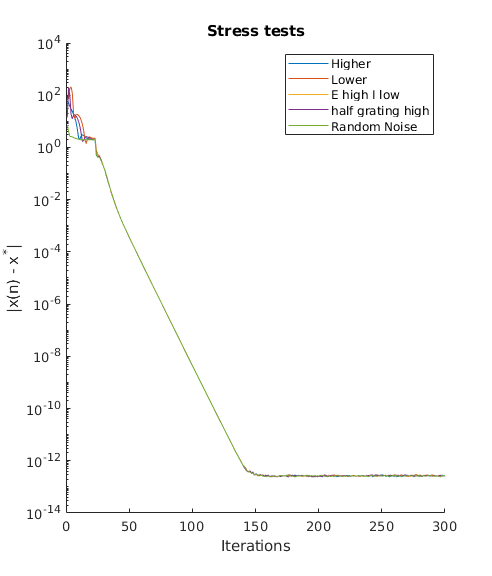

Fig4 = figure('Name','Fig3_EpocScan','units','normalized','outerposition',[-1,0,0.1,0.3]);
for TestInd = 1:length(LDEIniAll)
    hold on
    plot(L2Diff_OneStepAll(TestInd,:)/(N_HCOut^2*(1/2)),'DisplayName',IniDespt{TestInd})
end
set(gca, 'YScale', 'log')
xlabel('Iterations'); ylabel('|x(n) - x^*|')
title('Stress tests')
ylim([1e-14 1e4])
xlim([0 300])
legend

Save figures

FigName1 = sprintf('Figure4Draft');
savefig(Fig4,[FigurePaperPath FigName1 '.fig']);


Print Figs

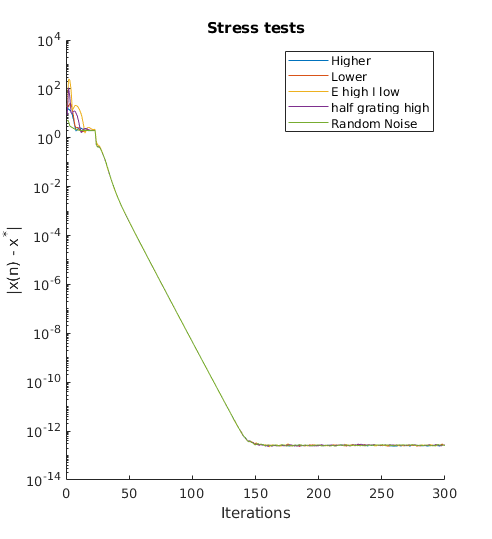

Fig4.PaperUnits = 'centimeters';
Fig4.PaperSize = [10,10];
Fig4.PaperOrientation = "landscape";
exportgraphics(Fig4,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)

investigate BG trajs

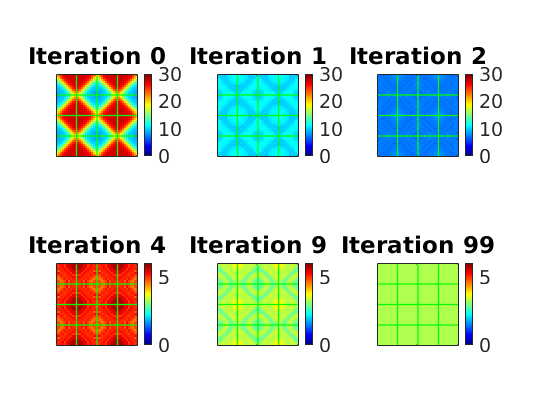

EpocList = [1:3, 5, 10, 100]; % for angles
Panel1 = 2; Panel2 = 3;%length(EpocList);
ha = tight_subplot(Panel1,Panel2,[.06 .06],[.08 .08],[.10 .10]);
LDEEpoOut = LDEEpoOutAll{1};
Caxe = [repmat([0 30],3,1);repmat([0 6],3,1)];
%Caxe = [repmat([0 50],4,1);repmat([0 35],4,1)];
%Caxe = [repmat([0 42],10,1)];
for EpocInd = 1:length(EpocList)
    Epoc = EpocList(EpocInd);
    %subplot(2,6,EpocInd+6*(ICInd-1))
    axes(ha(EpocInd));
    LDEPlot = LDEEpoOut{Epoc};
    ShowField(...
        LDEPlot.S*(1-CplxR)+LDEPlot.C*CplxR,...
        1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
        sprintf('Iteration %d',Epoc-1), Caxe(EpocInd,:)) % last input may catgorized cbar: ,, [5 60]
    set(gca,'fontsize',16)
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
    %xlabel(sprintf('|x(%d) - x^*| = %.2f',Epoc-1 , L2Diff_OneStepAll(1,Epoc)/(N_HCOut^2*(1/2))))
end